# Elaborato CN: Gradiente Coniugato

## Regressione Lineare

clear
clc

Caricamento del dataset

load carsmall

Stima dei consumi in termini di miglia per galloni (MPG) in funzione dei cavalli

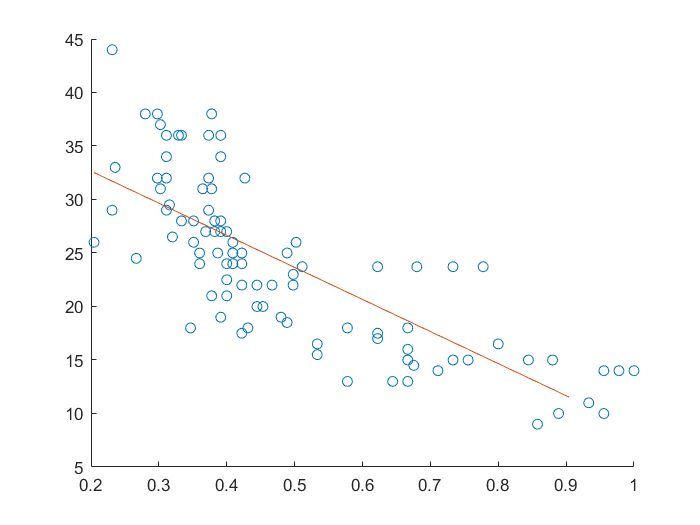

x_points = Horsepower;    % Contains NaN data
y_points = MPG;

x_points(isnan(x_points)) = mean(rmmissing(x_points));
y_points(isnan(y_points)) = mean(rmmissing(y_points));

x_points = x_points/max(x_points);

n = 1;
k_max = 100;
toll = 1e-6;

[p,res,iter,pvec,resvec] = poly_reg(x_points',y_points',n,k_max,toll,'cg');

x = min(x_points):0.1:max(x_points);
y = polyval(p,x);

scatter(x_points, y_points)
hold on
plot(x,y)
hold off

Andamento dell'errore:

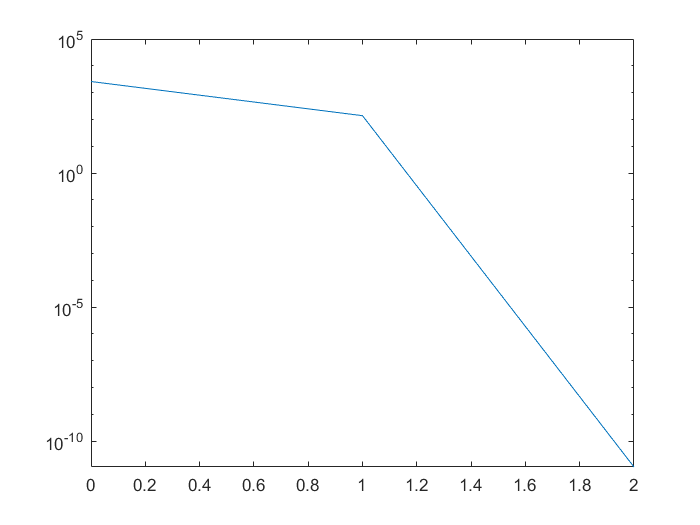

iter = 0:iter;
semilogy(iter,resvec)

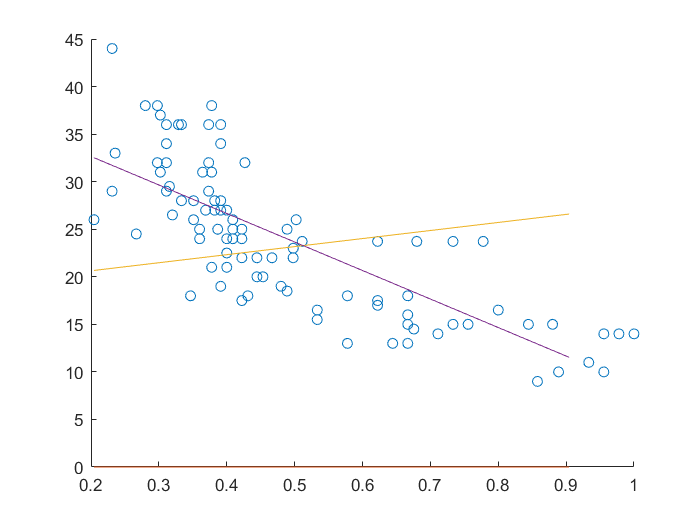

scatter(x_points, y_points)
hold on

x = min(x_points):0.1:max(x_points);

for k=1:size(pvec,2)
    y = polyval(pvec(:,k),x);
    plot(x,y)
end
hold off

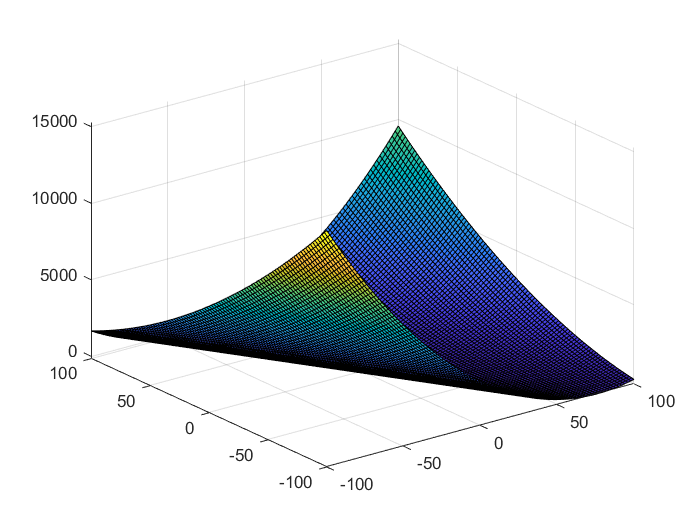

m = size(x_points,2);
n = n+1;
    
A = zeros(m,n);
for k=1:m
    for j=1:n
        A(k,j) = x_points(k)^(j-1);
    end
end
    
B = A'*A;
d = A'*y_points';

x1 = -100:2:100;
x2 = -100:2:100;
[X1,X2] = meshgrid(x1,x2);

E = (1/2)*(B(1,1)*X1.^2+(B(1,2)+B(2,1))*X1.*X2+B(2,2)*X2.^2)-(d(1)*X1+d(2)*X2);
surf(X1,X2,E);

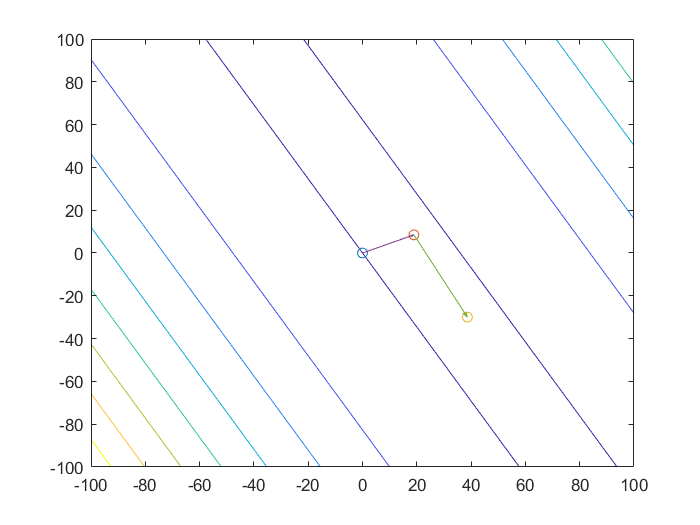


contour(X1,X2,E);
hold on

points = flip(pvec,1);
for k=1:size(points,2)
    scatter(points(1,k),points(2,k)); 
end

for k=1:size(points,2)-1
    P1 = points(:,k);
    P2 = points(:,k+1);
    D = P2-P1;
    quiver(P1(1),P1(2),D(1),D(2),0)
end
hold off